# DIGITAL IMAGE PROCESSING-1 

# (UE20EC317)

# MINI PTOJECT - SMART LICENSE PLATE RECOGNITION

TEAM:

NIKHI R.S (PES1UG20EC125)

PRANAV .S (PES1UG20EC138)

PRUTHVI HARITHAS (PES1UG20EC145)

MAIN FILE

clear;
close all;

## **Reading the image from the library of captured vehicle images**

Image = imread('C:\Users\pruth\OneDrive\Documents\PES\SEM V\Digital Image Processing\Lab\Assignments\Num\6.jpg');

## **Resizing image to be 480xNaN resolution, where NaN can be of any variable width**

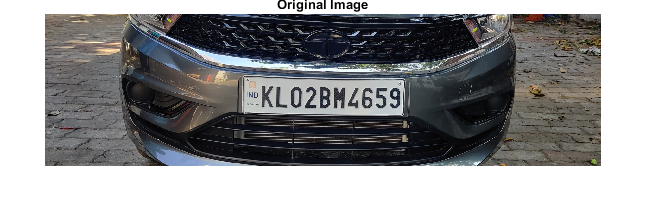

Image = imresize(Image, [480 NaN]);
Image1=Image;


figure; 
imshow(Image1);                                               % Shows the Original Image
title('Original Image')

## **Converting image to grayscale**

imgray = rgb2gray(Image);

## Applying a threshold function to the grayscale image 

threshold = graythresh(Image);
disp(threshold);

    0.3098



imbin =im2bw(Image,threshold);

## Applying Sobel Edge Detection technique to the image

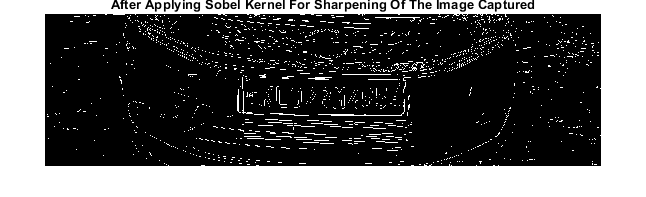

Image = edge(imgray, 'sobel');

figure; 
imshow(Image)                                                 % After applying sobel kernel for sharpening of the image
title("After Applying Sobel Kernel For Sharpening Of The Image Captured")

## Dilating the image on which the Sobel kernel was applied

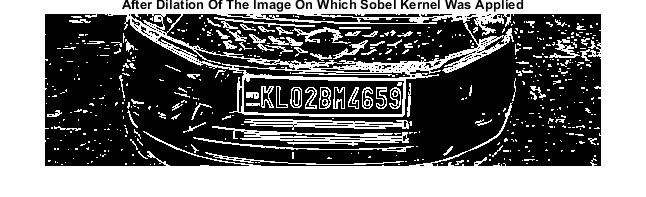

Image = imdilate(Image, strel('rectangle',[4 4]));
figure; 
imshow(Image)                                                 %After performing the dilation of the image on which sobel kernel was applied
title('After Dilation Of The Image On Which Sobel Kernel Was Applied')

## Performing filling and erosion operations on the image on which the Sobel kernel was applied

Image = imfill(Image, 'holes');
Image = imerode(Image, strel('diamond',10));

## Finding the location of the number plate in the image and localizing it using the Bounding Box method

Iprops=regionprops(Image,'BoundingBox','Area', 'Image');
area = Iprops.Area;
count = numel(Iprops);
maxa= area;
boundingBox = Iprops.BoundingBox;

for i=1:count
   if maxa<Iprops(i).Area
       maxa=Iprops(i).Area;
       boundingBox=Iprops(i).BoundingBox;
   end
end    

## Performing suitable operations on the localized image of the number plate

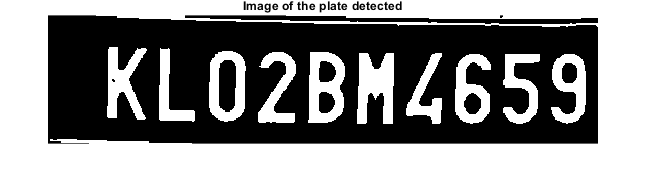

Image = imcrop(imbin, boundingBox);
Image = imresize(Image, [240 NaN]);                          %Resize number plate to 240xNaN
Image = imopen(Image, strel('rectangle', [4 4]));            %clear dust from the image
Image = bwareaopen(~Image, 500);                             %Remove some object if it width is too long or too small than 500
 [h, w] = size(Image);                                       %%%get width
figure; 
imshow(Image);                                               %Image of the plate detected after localization and a few Image processing techniques
title('Image of the plate detected')

## Character Segmentation, Optical Character Recognition using Template Matching Method, Character Aggregation

NOTE: Template is matched using another file: Number_Plate_Detection_Template_Creation, Number_Plate_Detection_Read which creates a library of characters from A-Z and 0-9 which serves as a Templates File or Templates Library for matching the characters read from the plate.

Iprops=regionprops(Image,'BoundingBox','Area', 'Image');
count = numel(Iprops);

number_plate=[];                                              % Initializing the variable of number plate string.

for i=1:count
   ow = length(Iprops(i).Image(1,:));
   oh = length(Iprops(i).Image(:,1));
   if ow<(h/2) && oh>(h/3)
       letter=Number_Plate_Detection_Read(Iprops(i).Image);                          % Reading the letter corresponding the binary image 'N'.                                                                             %figure; imshow(Iprops(i).Image);
       number_plate=[number_plate letter];                    % Appending every subsequent character in noPlate array.
   end
end

## Obtaining the results

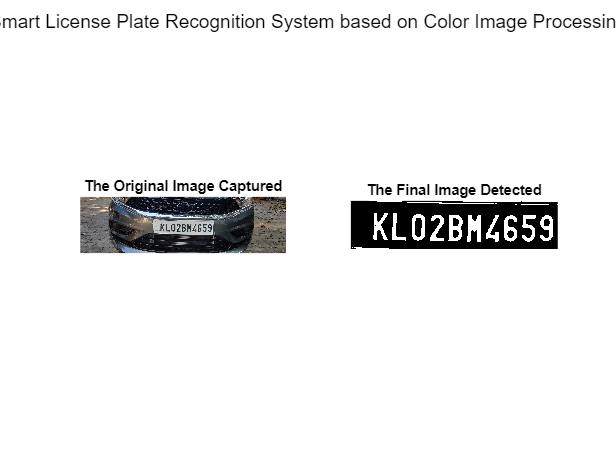

figure;
subplot(1,2,1)
imshow(Image1);                                               % Original Image
title('The Original Image Captured')

subplot(1,2,2)
imshow(Image);                                                % Image of the plate detected
title('The Final Image Detected')



sgtitle('Smart License Plate Recognition System based on Color Image Processing')